clear all

% Model Parameters (extracted from Table S1 in SI)
% ====================================================
%                  [Unit]   Variable definition
% ====================================================
n_m = 75;          %          Number of myosin motors
F_m = -2;          % [pN]     Single myosin motor stall force
v_u = -120;        % [nm/s]   Unloaded myosin motor velocity
n_c = 75;          %          Number of molecular clutches
k_on = 1;          % [s^(-1)] Rate of clutch binding
k_off = 0.1;       % [s^(-1)] Rate of clutch unbinding
F_b = -2;      % [pN]     Characteristic bond rupture force
k_clutch = 5;      % [pN/nm]  Molecular clutch spring constant

function [is_bind, state_idx, dt] = simulate_next_event(clutch_states, F_clutch, k_on, F_b, k_off)
    % Gillepsie algorithm implementation
    unengaged_clutch_indices = find(clutch_states==0);
    engaged_clutch_indices = find(clutch_states==1);

    if isempty(unengaged_clutch_indices)
        t_bind=inf;
    else
        t_bind=-log(rand(1, length(unengaged_clutch_indices)))/k_on;
    end

    if isempty(engaged_clutch_indices)
        t_unbind=inf;
    else
        t_unbind=-log(rand(1, length(engaged_clutch_indices)))/(k_off * exp(F_clutch / F_b));
    end

    [min_t_unbind, unbind_idx] = min(t_unbind);
    [min_t_bind, bind_idx] = min(t_bind);
    
    if min_t_bind < min_t_unbind
        % Binding event happens first
        is_bind = 1;
        state_idx = unengaged_clutch_indices(bind_idx);
        dt = min_t_bind;
    else
        % Unbinding event happens first
        is_bind = 0;
        state_idx = engaged_clutch_indices(unbind_idx);
        dt = min_t_unbind;
    end
end

% Running Variables
n_mus = 100;
mus = logspace(-5, 2, n_mus);
events_simulated = 1e4;
v_filaments_t = zeros(1, events_simulated);
dts = zeros(1, events_simulated);
clutch_states = zeros(1, n_c);
average_vs = zeros(1, n_mus);

% Surface viscosity simulation
tic
i = 1;
for mu = mus
    for ii = 1:events_simulated
        n_eng = length(find(clutch_states==1));
        F_sub = v_u / ((1 / (n_eng * mu)) + (v_u / (n_m * F_m)));
        v_filament = v_u * (1 - ((F_sub) / (n_m * F_m)));
        if v_filament > 0
            v_filament = 0;
        end
        F_clutch = mu * v_filament;
        
        [is_bind, state_idx, dt] = simulate_next_event(clutch_states, F_clutch, k_on, F_b, k_off);
        clutch_states(state_idx) = is_bind;
    
        v_filaments_t(ii) = v_filament;
        dts(ii) = dt;
    end
    average_vs(i) = sum(v_filaments_t .* dts) / sum(dts);
    i = i + 1;
end
toc

Elapsed time is 6.770348 seconds.


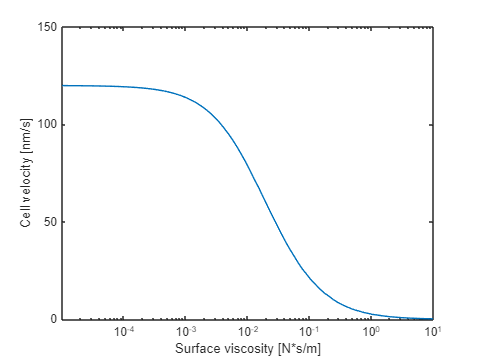

semilogx(mus, -average_vs, '-');
ylim([0 150]);
xlim([1e-5 1e1]);
xlabel("Surface viscosity [N*s/m]");
ylabel("Cell velocity [nm/s]");